clear all 
close all 
grid on 

%Variabes:
f = 24

f = 24

T = 1/f

T = 0.0417

N = 880 %nb d'échantillons

N = 880

fe = 2200 %fréquence d'échantillonnage supérieure à 2f

fe = 2200


Nf = 880 +10000%Créer suite à la création d'un 0 padding sur y

Nf = 10880


k = 0:N-1 %indice axe abscisse qu'on répète N fois

k =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


k_Nf = 0:Nf-1 %indice axe abscisse qu'on répète Nf fois (0 padding -> y)

k_Nf =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49



% intervalle axe abscisses qui dépend de fe et de l'indice temporel
t = k*(1/fe)

t =          0    0.0005    0.0009    0.0014    0.0018    0.0023    0.0027    0.0032    0.0036    0.0041    0.0045    0.0050    0.0055    0.0059    0.0064    0.0068    0.0073    0.0077    0.0082    0.0086    0.0091    0.0095    0.0100    0.0105    0.0109    0.0114    0.0118    0.0123    0.0127    0.0132    0.0136    0.0141    0.0145    0.0150    0.0155    0.0159    0.0164    0.0168    0.0173    0.0177    0.0182    0.0186    0.0191    0.0195    0.0200    0.0205    0.0209    0.0214    0.0218    0.0223



%intervalle fréquenciel de mes fft 
f1 = k*fe/N %axe fréquentiel du signal x

f1 = 	1.0e+03 *

         0    0.0025    0.0050    0.0075    0.0100    0.0125    0.0150    0.0175    0.0200    0.0225    0.0250    0.0275    0.0300    0.0325    0.0350    0.0375    0.0400    0.0425    0.0450    0.0475    0.0500    0.0525    0.0550    0.0575    0.0600    0.0625    0.0650    0.0675    0.0700    0.0725    0.0750    0.0775    0.0800    0.0825    0.0850    0.0875    0.0900    0.0925    0.0950    0.0975    0.1000    0.1025    0.1050    0.1075    0.1100    0.1125    0.1150    0.1175    0.1200    0.1225


f1_Nf = k_Nf*fe/Nf %axe fréquentiel en lien avec le 0 padding

f1_Nf = 	1.0e+03 *

         0    0.0002    0.0004    0.0006    0.0008    0.0010    0.0012    0.0014    0.0016    0.0018    0.0020    0.0022    0.0024    0.0026    0.0028    0.0030    0.0032    0.0034    0.0036    0.0038    0.0040    0.0042    0.0044    0.0047    0.0049    0.0051    0.0053    0.0055    0.0057    0.0059    0.0061    0.0063    0.0065    0.0067    0.0069    0.0071    0.0073    0.0075    0.0077    0.0079    0.0081    0.0083    0.0085    0.0087    0.0089    0.0091    0.0093    0.0095    0.0097    0.0099



%Signaux
x = cos(2*pi*f*t) 

x =     1.0000    0.9977    0.9906    0.9789    0.9626    0.9418    0.9166    0.8871    0.8534    0.8157    0.7741    0.7290    0.6804    0.6286    0.5738    0.5164    0.4565    0.3945    0.3307    0.2653    0.1986    0.1310    0.0628   -0.0057   -0.0742   -0.1423   -0.2098   -0.2762   -0.3414   -0.4050   -0.4667   -0.5261   -0.5832   -0.6374   -0.6887   -0.7367   -0.7813   -0.8222   -0.8593   -0.8923   -0.9211   -0.9456   -0.9657   -0.9812   -0.9921   -0.9984   -0.9999   -0.9968   -0.9890   -0.9765


x2 = [x, zeros(1,10000)] %10000 = nb zeros ajoutés -> en tenir compte pour Nf

x2 =     1.0000    0.9977    0.9906    0.9789    0.9626    0.9418    0.9166    0.8871    0.8534    0.8157    0.7741    0.7290    0.6804    0.6286    0.5738    0.5164    0.4565    0.3945    0.3307    0.2653    0.1986    0.1310    0.0628   -0.0057   -0.0742   -0.1423   -0.2098   -0.2762   -0.3414   -0.4050   -0.4667   -0.5261   -0.5832   -0.6374   -0.6887   -0.7367   -0.7813   -0.8222   -0.8593   -0.8923   -0.9211   -0.9456   -0.9657   -0.9812   -0.9921   -0.9984   -0.9999   -0.9968   -0.9890   -0.9765


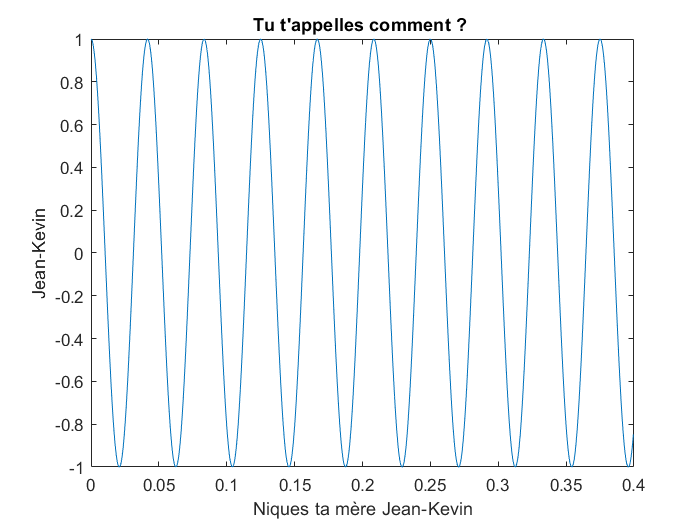


%affichage question n°2)
plot(t,x)
title("Tu t'appelles comment ? ")
xlabel("Niques ta mère Jean-Kevin")
ylabel("Jean-Kevin")


%obligation de passer par la valeur absolue pour virer les complexes lors
%de l'affichage des courbes.
X = fft(x)

X = 	1.0e+02 *

  -0.0767 + 0.0000i  -0.0776 + 0.0278i  -0.0806 + 0.0575i  -0.0860 + 0.0914i  -0.0947 + 0.1331i  -0.1086 + 0.1887i  -0.1316 + 0.2708i  -0.1740 + 0.4110i  -0.2716 + 0.7199i  -0.6991 + 2.0434i   1.0171 - 3.2316i   0.2831 - 0.9663i   0.1615 - 0.5864i   0.1119 - 0.4285i   0.0852 - 0.3414i   0.0686 - 0.2859i   0.0573 - 0.2473i   0.0492 - 0.2186i   0.0432 - 0.1965i   0.0385 - 0.1789i   0.0348 - 0.1644i   0.0317 - 0.1523i   0.0292 - 0.1420i   0.0272 - 0.1332i   0.0254 - 0.1254i   0.0239 - 0.1186i   0.0226 - 0.1126i   0.0215 - 0.1071i   0.0205 - 0.1022i   0.0196 - 0.0978i   0.0189 - 0.0938i   0.0182 - 0.0901i   0.0176 - 0.0867i   0.0170 - 0.0835i   0.0165 - 0.0806i   0.0161 - 0.0779i   0.0156 - 0.0754i   0.0153 - 0.0730i   0.0149 - 0.0708i   0.0146 - 0.0687i   0.0143 - 0.0668i   0.0141 - 0.0649i   0.0138 - 0.0632i   0.0136 - 0.0615i   0.0134 - 0.0600i   0.0132 - 0.0585i   0.0130 - 0.0571i   0.0128 - 0.0557i   0.0127 - 0.0545i   0.0125 - 0.0532i


magX = abs(X)

magX =     7.6675    8.2445    9.8980   12.5493   16.3356   21.7701   30.1061   44.6327   76.9392  215.9634  338.7866  100.6871   60.8204   44.2886   35.1908   29.4039   25.3810   22.4108   20.1203   18.2950   16.8025   15.5569   14.4996   13.5895   12.7967   12.0991   11.4800   10.9261   10.4275    9.9758    9.5645    9.1881    8.8423    8.5234    8.2281    7.9539    7.6985    7.4600    7.2366    7.0271    6.8299    6.6442    6.4688    6.3029    6.1457    5.9966    5.8549    5.7201    5.5916    5.4690



X2 = fft(x2)

X2 = 	1.0e+02 *

  -0.0767 + 0.0000i  -0.0659 + 0.0418i  -0.0363 + 0.0730i   0.0042 + 0.0855i   0.0450 + 0.0763i   0.0753 + 0.0483i   0.0871 + 0.0090i   0.0772 - 0.0309i   0.0481 - 0.0604i   0.0074 - 0.0715i  -0.0341 - 0.0607i  -0.0655 - 0.0305i  -0.0784 + 0.0116i  -0.0693 + 0.0549i  -0.0404 + 0.0882i   0.0007 + 0.1031i   0.0434 + 0.0957i   0.0762 + 0.0682i   0.0905 + 0.0279i   0.0823 - 0.0141i   0.0534 - 0.0465i   0.0114 - 0.0603i  -0.0328 - 0.0511i  -0.0676 - 0.0208i  -0.0836 + 0.0232i  -0.0762 + 0.0698i  -0.0473 + 0.1071i  -0.0040 + 0.1254i   0.0424 + 0.1201i   0.0795 + 0.0925i   0.0976 + 0.0499i   0.0913 + 0.0038i   0.0621 - 0.0333i   0.0172 - 0.0510i  -0.0318 - 0.0438i  -0.0720 - 0.0128i  -0.0926 + 0.0347i  -0.0877 + 0.0869i  -0.0581 + 0.1305i  -0.0111 + 0.1543i   0.0411 + 0.1519i   0.0850 + 0.1239i   0.1088 + 0.0775i   0.1055 + 0.0252i   0.0756 - 0.0190i   0.0262 - 0.0427i  -0.0301 - 0.0385i  -0.0786 - 0.0064i  -0.1062 + 0.0464i  -0.1051 + 0.1071i


magX2 = abs(X2)

magX2 =     7.6675    7.8041    8.1507    8.5575    8.8630    8.9474    8.7560    8.3111    7.7218    7.1881    6.9631    7.2222    7.9223    8.8372    9.7036   10.3079   10.5059   10.2257    9.4725    8.3462    7.0841    6.1331    6.0749    7.0743    8.6710   10.3350   11.7050   12.5512   12.7351   12.1966   10.9574    9.1409    7.0446    5.3775    5.4150    7.3159    9.8884   12.3469   14.2884   15.4684   15.7369   15.0267   13.3566   10.8485    7.7929    5.0063    4.8908    7.8857   11.5910   15.0053


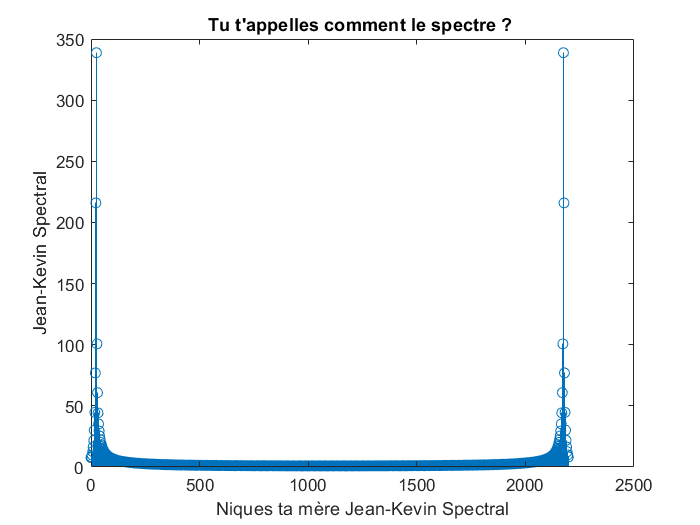


%question 3°) 
%La durée d'observation du signal va de 0 à NTe secondes.

%question 4°) 
%A priori, l'allure du spectre sera un pic en f et un pic en fe-f et fe+f. 
% Sur un support illimité : on obtient Nfe +/- f 
% Sur un support borné : on obtient juste f et fe-f | fe+f

%affichage spectre de x
stem(f1,magX)
title("Tu t'appelles comment le spectre ? ")
xlabel("Niques ta mère Jean-Kevin Spectral")
ylabel("Jean-Kevin Spectral")

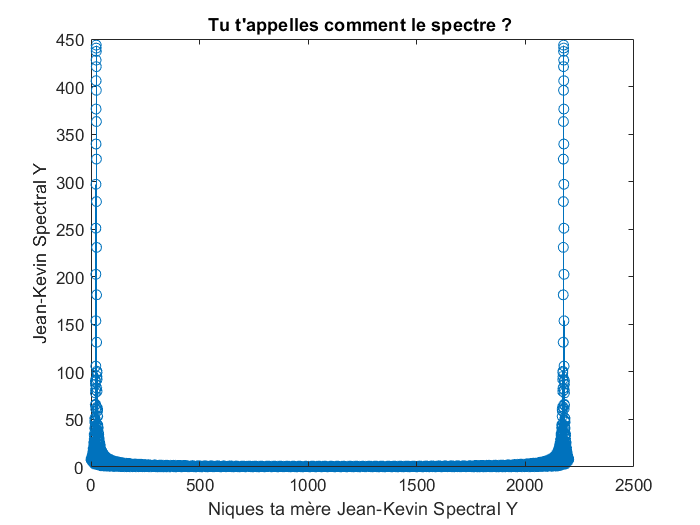


%affichage optimal spectre x avec zero padding (question 5°))
stem(f1_Nf,magX2)
title("Tu t'appelles comment le spectre ? ")
xlabel("Niques ta mère Jean-Kevin Spectral Y")
ylabel("Jean-Kevin Spectral Y")



%Variables question 6°)
ks_Nf = -Nf/2:Nf/2-1 %attention indice axe abscisse entre -Nf/2 et Nf/2 

ks_Nf =        -5440       -5439       -5438       -5437       -5436       -5435       -5434       -5433       -5432       -5431       -5430       -5429       -5428       -5427       -5426       -5425       -5424       -5423       -5422       -5421       -5420       -5419       -5418       -5417       -5416       -5415       -5414       -5413       -5412       -5411       -5410       -5409       -5408       -5407       -5406       -5405       -5404       -5403       -5402       -5401       -5400       -5399       -5398       -5397       -5396       -5395       -5394       -5393       -5392       -5391


fs_Nf = (ks_Nf - 0.5)*fe/Nf % axe fréquentiel en fonction de Nf et fe et le -0.5 demandé.

fs_Nf = 	1.0e+03 *

   -1.1001   -1.0999   -1.0997   -1.0995   -1.0993   -1.0991   -1.0989   -1.0987   -1.0985   -1.0983   -1.0981   -1.0979   -1.0977   -1.0975   -1.0973   -1.0971   -1.0969   -1.0967   -1.0965   -1.0963   -1.0961   -1.0959   -1.0957   -1.0955   -1.0952   -1.0950   -1.0948   -1.0946   -1.0944   -1.0942   -1.0940   -1.0938   -1.0936   -1.0934   -1.0932   -1.0930   -1.0928   -1.0926   -1.0924   -1.0922   -1.0920   -1.0918   -1.0916   -1.0914   -1.0912   -1.0910   -1.0908   -1.0906   -1.0904   -1.0902


X2s_Nf = fftshift(magX2) %fftshift de l'abs(fft(x))

X2s_Nf =     0.9146    0.8855    0.8001    0.6641    0.4869    0.2826    0.0952    0.2065    0.4148    0.6038    0.7561    0.8607    0.9107    0.9028    0.8374    0.7189    0.5553    0.3587    0.1520    0.1354    0.3399    0.5387    0.7058    0.8287    0.8992    0.9124    0.8676    0.7677    0.6193    0.4330    0.2252    0.0880    0.2635    0.4693    0.6496    0.7898    0.8801    0.9144    0.8905    0.8100    0.6783    0.5043    0.3016    0.1061    0.1880    0.3964    0.5881    0.7442    0.8535    0.9087


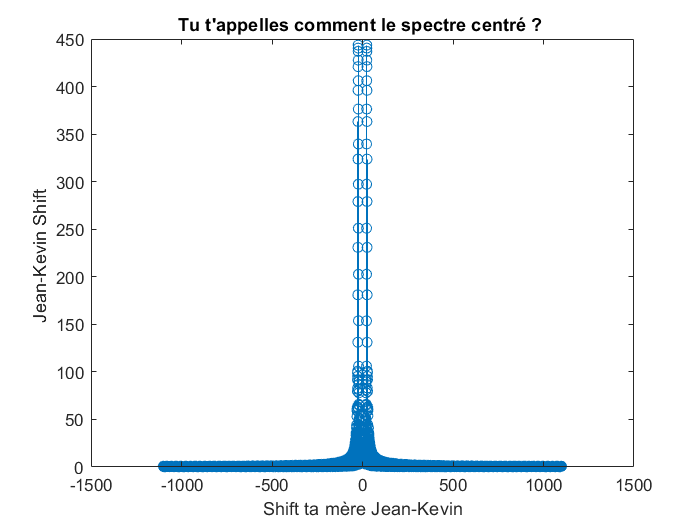



%affichage spectre de y (analyse optimale entre -0.5fe et 0.5fe (1100 Hz) -> question 6°))
stem(fs_Nf,X2s_Nf)
title("Tu t'appelles comment le spectre centré ? ")
xlabel("Shift ta mère Jean-Kevin")
ylabel("Jean-Kevin Shift ")


%question 7°) 
%La résolution fréquentielle ou l'intervalle de fréquence entre deux points
%consécutifs est égale à fe/Nf soit NfTe : on échantillonne à chaque point
%Nf tout les Te. 

%question 8°) 
%On obtient une fft centrée en 0 allant de -1100 Hz à 1100 Hz. Le signal
%est optimisé avec le 0 padding. On obtient uniquement deux raies en -f et
%f : c'est normal : on n'affiche pas fe +/- f car il n'est pas compris dans
%l'intervale [-0.5fe, 0.5fe].


%quesion 9°) 
%Pour plus de lisibilité, nous déclarerons les variables pour cette
%question ici.

%variables 
fm = 200 %fréquence du signal y 

fm = 200


%Signaux
y = cos(2*pi*fm*t) %t le même intervalle pour l'axe des abscisses que précedemment

y =     1.0000    0.8413    0.4154   -0.1423   -0.6549   -0.9595   -0.9595   -0.6549   -0.1423    0.4154    0.8413    1.0000    0.8413    0.4154   -0.1423   -0.6549   -0.9595   -0.9595   -0.6549   -0.1423    0.4154    0.8413    1.0000    0.8413    0.4154   -0.1423   -0.6549   -0.9595   -0.9595   -0.6549   -0.1423    0.4154    0.8413    1.0000    0.8413    0.4154   -0.1423   -0.6549   -0.9595   -0.9595   -0.6549   -0.1423    0.4154    0.8413    1.0000    0.8413    0.4154   -0.1423   -0.6549   -0.9595


z = y.*x %multiplication des signaux nécessite "*" pour éviter les erreurs de dimensions entre les signaux 

z =     1.0000    0.8393    0.4115   -0.1393   -0.6304   -0.9037   -0.8795   -0.5809   -0.1214    0.3388    0.6512    0.7290    0.5724    0.2611   -0.0817   -0.3382   -0.4380   -0.3785   -0.2165   -0.0377    0.0825    0.1102    0.0628   -0.0048   -0.0308    0.0203    0.1374    0.2651    0.3276    0.2652    0.0664   -0.2186   -0.4906   -0.6374   -0.5794   -0.3061    0.1112    0.5384    0.8245    0.8562    0.6032    0.1346   -0.4012   -0.8254   -0.9921   -0.8399   -0.4154    0.1419    0.6477    0.9370


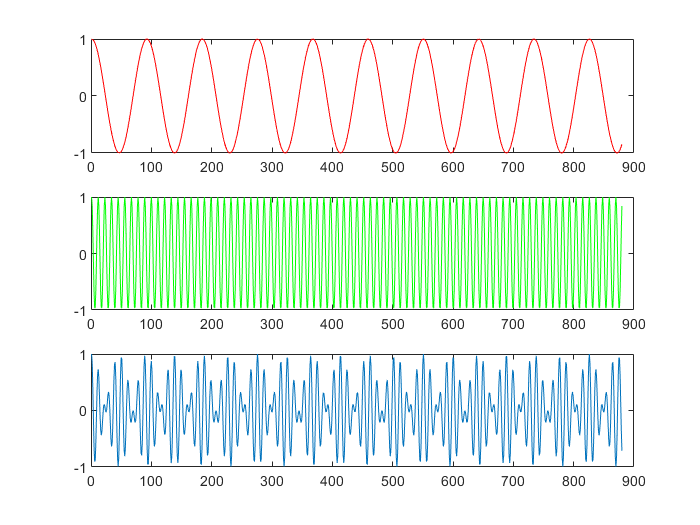


%affichage question 9°) 
%subplot (a,b,c) : 
    % a : nombre de plot à afficher (nombre de lignes d'une matrice)
    % b : nombre de colonne alloué dans une matrice pour afficher les plots
    % c : le numéro du plot afin que subplot sache ou l'afficher dans sa
    % matrice. 
    
%Ici on défini une matrice de (3,1) pour 3 plots
subplot(3,1,1),plot(x,'r');
subplot(3,1,2),plot(y,'g');
subplot(3,1,3),plot(z);



%question 10 ET 11°) : analyse spectrale
%Ici, on ne nous demande pas une analyse optimale des signaux en
%introduisant un 0 padding. C'est pourquoi notre nombre d'échantillons Nf
%pour l'analyse spectrale est égal à N soit 880 échantillons. 

ks_N = -N/2:N/2-1 %attention indice axe abscisse entre -N/2 et N/2 puisque Nf = N

ks_N =   -440  -439  -438  -437  -436  -435  -434  -433  -432  -431  -430  -429  -428  -427  -426  -425  -424  -423  -422  -421  -420  -419  -418  -417  -416  -415  -414  -413  -412  -411  -410  -409  -408  -407  -406  -405  -404  -403  -402  -401  -400  -399  -398  -397  -396  -395  -394  -393  -392  -391


fs_N = (ks_N - 0.5)*fe/N % axe fréquentiel en fonction de N et fe et le -0.5 demandé.

fs_N = 	1.0e+03 *

   -1.1013   -1.0987   -1.0962   -1.0938   -1.0913   -1.0888   -1.0862   -1.0837   -1.0813   -1.0788   -1.0762   -1.0737   -1.0713   -1.0688   -1.0662   -1.0637   -1.0613   -1.0588   -1.0562   -1.0537   -1.0513   -1.0488   -1.0462   -1.0437   -1.0413   -1.0388   -1.0362   -1.0337   -1.0313   -1.0288   -1.0263   -1.0237   -1.0212   -1.0188   -1.0163   -1.0137   -1.0112   -1.0088   -1.0063   -1.0037   -1.0012   -0.9988   -0.9962   -0.9938   -0.9912   -0.9888   -0.9862   -0.9838   -0.9812   -0.9788



%Mise en place des valeurs absolues des fft des 3 signaux x(t), y(t), z(t)
X = fft(x)

X = 	1.0e+02 *

  -0.0767 + 0.0000i  -0.0776 + 0.0278i  -0.0806 + 0.0575i  -0.0860 + 0.0914i  -0.0947 + 0.1331i  -0.1086 + 0.1887i  -0.1316 + 0.2708i  -0.1740 + 0.4110i  -0.2716 + 0.7199i  -0.6991 + 2.0434i   1.0171 - 3.2316i   0.2831 - 0.9663i   0.1615 - 0.5864i   0.1119 - 0.4285i   0.0852 - 0.3414i   0.0686 - 0.2859i   0.0573 - 0.2473i   0.0492 - 0.2186i   0.0432 - 0.1965i   0.0385 - 0.1789i   0.0348 - 0.1644i   0.0317 - 0.1523i   0.0292 - 0.1420i   0.0272 - 0.1332i   0.0254 - 0.1254i   0.0239 - 0.1186i   0.0226 - 0.1126i   0.0215 - 0.1071i   0.0205 - 0.1022i   0.0196 - 0.0978i   0.0189 - 0.0938i   0.0182 - 0.0901i   0.0176 - 0.0867i   0.0170 - 0.0835i   0.0165 - 0.0806i   0.0161 - 0.0779i   0.0156 - 0.0754i   0.0153 - 0.0730i   0.0149 - 0.0708i   0.0146 - 0.0687i   0.0143 - 0.0668i   0.0141 - 0.0649i   0.0138 - 0.0632i   0.0136 - 0.0615i   0.0134 - 0.0600i   0.0132 - 0.0585i   0.0130 - 0.0571i   0.0128 - 0.0557i   0.0127 - 0.0545i   0.0125 - 0.0532i


magX = abs(X)

magX =     7.6675    8.2445    9.8980   12.5493   16.3356   21.7701   30.1061   44.6327   76.9392  215.9634  338.7866  100.6871   60.8204   44.2886   35.1908   29.4039   25.3810   22.4108   20.1203   18.2950   16.8025   15.5569   14.4996   13.5895   12.7967   12.0991   11.4800   10.9261   10.4275    9.9758    9.5645    9.1881    8.8423    8.5234    8.2281    7.9539    7.6985    7.4600    7.2366    7.0271    6.8299    6.6442    6.4688    6.3029    6.1457    5.9966    5.8549    5.7201    5.5916    5.4690


Y = fft(y)

Y = 	1.0e+02 *

  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i


magY = abs(Y)

magY =     0.0125    0.0162    0.0087    0.0250    0.0276    0.0465    0.0115    0.0371    0.0318    0.0219    0.0187    0.0698    0.1025    0.0191    0.1249    0.0551    0.0278    0.0306    0.0421    0.0088    0.0109    0.0132    0.0219    0.0086    0.0335    0.0252    0.0136    0.0042    0.0081    0.0352    0.0184    0.0498    0.0562    0.0553    0.0482    0.0532    0.0645    0.0717    0.0502    0.0054    0.0290    0.0108    0.0214    0.0354    0.0500    0.0141    0.0050    0.0137    0.0274    0.0369


Z= fft(z)

Z = 	1.0e+02 *

   0.0103 + 0.0000i   0.0103 + 0.0004i   0.0103 + 0.0008i   0.0103 + 0.0013i   0.0103 + 0.0017i   0.0103 + 0.0021i   0.0104 + 0.0026i   0.0104 + 0.0030i   0.0104 + 0.0034i   0.0104 + 0.0039i   0.0104 + 0.0043i   0.0104 + 0.0048i   0.0104 + 0.0052i   0.0104 + 0.0057i   0.0105 + 0.0061i   0.0105 + 0.0066i   0.0105 + 0.0071i   0.0105 + 0.0076i   0.0105 + 0.0081i   0.0106 + 0.0086i   0.0106 + 0.0091i   0.0106 + 0.0096i   0.0107 + 0.0102i   0.0107 + 0.0107i   0.0107 + 0.0113i   0.0108 + 0.0119i   0.0108 + 0.0125i   0.0109 + 0.0131i   0.0109 + 0.0137i   0.0110 + 0.0144i   0.0110 + 0.0150i   0.0111 + 0.0157i   0.0112 + 0.0164i   0.0113 + 0.0172i   0.0113 + 0.0180i   0.0114 + 0.0188i   0.0115 + 0.0196i   0.0116 + 0.0205i   0.0117 + 0.0214i   0.0118 + 0.0224i   0.0120 + 0.0234i   0.0121 + 0.0245i   0.0123 + 0.0256i   0.0124 + 0.0268i   0.0126 + 0.0281i   0.0128 + 0.0294i   0.0130 + 0.0309i   0.0133 + 0.0324i   0.0136 + 0.0341i   0.0139 + 0.0359i


magZ = abs(Z)

magZ =     1.0332    1.0341    1.0369    1.0416    1.0481    1.0564    1.0666    1.0786    1.0925    1.1081    1.1255    1.1447    1.1657    1.1884    1.2129    1.2392    1.2672    1.2970    1.3287    1.3621    1.3975    1.4347    1.4738    1.5150    1.5582    1.6035    1.6511    1.7009    1.7532    1.8080    1.8654    1.9257    1.9889    2.0554    2.1252    2.1986    2.2759    2.3573    2.4433    2.5342    2.6304    2.7325    2.8408    2.9562    3.0793    3.2109    3.3521    3.5039    3.6677    3.8450



%Mise en place des 3 fftshifts prenant en compte les fft précédentes
Xs = fftshift(magX)

Xs =     0.9146    0.9146    0.9146    0.9146    0.9147    0.9147    0.9148    0.9149    0.9150    0.9151    0.9152    0.9153    0.9154    0.9156    0.9157    0.9159    0.9161    0.9163    0.9165    0.9167    0.9169    0.9172    0.9174    0.9177    0.9180    0.9182    0.9185    0.9189    0.9192    0.9195    0.9199    0.9202    0.9206    0.9210    0.9214    0.9218    0.9222    0.9226    0.9231    0.9235    0.9240    0.9245    0.9250    0.9255    0.9260    0.9265    0.9271    0.9276    0.9282    0.9288


Ys = fftshift(magY)

Ys =     0.0017    0.0010    0.0099    0.0089    0.0036    0.0125    0.0013    0.0049    0.0044    0.0198    0.0058    0.0409    0.0305    0.0203    0.0367    0.0174    0.0032    0.0237    0.0167    0.0220    0.0209    0.0122    0.0122    0.0008    0.0203    0.0153    0.0229    0.0331    0.0172    0.0217    0.0262    0.0058    0.0945    0.1730    0.1829    0.1047    0.0418    0.0289    0.0500    0.0294    0.0392    0.0459    0.0226    0.0216    0.0199    0.0092    0.0311    0.0411    0.0439    0.0031


Zs = fftshift(magZ)

Zs =     0.9155    0.9155    0.9155    0.9155    0.9156    0.9156    0.9157    0.9158    0.9159    0.9160    0.9161    0.9163    0.9165    0.9166    0.9168    0.9170    0.9172    0.9175    0.9177    0.9180    0.9182    0.9185    0.9188    0.9191    0.9195    0.9198    0.9202    0.9205    0.9209    0.9213    0.9217    0.9221    0.9226    0.9230    0.9235    0.9240    0.9245    0.9250    0.9255    0.9261    0.9266    0.9272    0.9278    0.9284    0.9290    0.9297    0.9303    0.9310    0.9316    0.9323



%Affichage des fftshift 
figure(2); %nécessaire de créer une nouvelle figure sinon subplot écrase ses résultats précedents. 
subplot(4,1,1),stem(fs_N, Xs, 'r');
subplot(4,1,2),stem(fs_N, Ys, 'g');
subplot(4,1,3),stem(fs_N, Zs);

%question 12°) 
%Les fréquences présentes dans le signal transmis Z correpondent bien aux
%deux fréquences f et fm des signaux X et Y. Encore une fois, seules +/- f
%et +/- fm sont représentées car nous enlevons de l'analyse la fréquence
%d'échantillonnage à 2200 Hz. 

%question 13°) 
% Le but de cette question est de retrouver x(t) à partir de z(t).
%On n'oublie pas le "." pour éviter les erreurs de dimensions entre les
%deux signaux. 
d = z./y % On demande ici un produit... une division est un produit ;)

d =     1.0000    0.9977    0.9906    0.9789    0.9626    0.9418    0.9166    0.8871    0.8534    0.8157    0.7741    0.7290    0.6804    0.6286    0.5738    0.5164    0.4565    0.3945    0.3307    0.2653    0.1986    0.1310    0.0628   -0.0057   -0.0742   -0.1423   -0.2098   -0.2762   -0.3414   -0.4050   -0.4667   -0.5261   -0.5832   -0.6374   -0.6887   -0.7367   -0.7813   -0.8222   -0.8593   -0.8923   -0.9211   -0.9456   -0.9657   -0.9812   -0.9921   -0.9984   -0.9999   -0.9968   -0.9890   -0.9765



%question 14°) 
D = fft(d)

D = 	1.0e+02 *

  -0.0767 + 0.0000i  -0.0776 + 0.0278i  -0.0806 + 0.0575i  -0.0860 + 0.0914i  -0.0947 + 0.1331i  -0.1086 + 0.1887i  -0.1316 + 0.2708i  -0.1740 + 0.4110i  -0.2716 + 0.7199i  -0.6991 + 2.0434i   1.0171 - 3.2316i   0.2831 - 0.9663i   0.1615 - 0.5864i   0.1119 - 0.4285i   0.0852 - 0.3414i   0.0686 - 0.2859i   0.0573 - 0.2473i   0.0492 - 0.2186i   0.0432 - 0.1965i   0.0385 - 0.1789i   0.0348 - 0.1644i   0.0317 - 0.1523i   0.0292 - 0.1420i   0.0272 - 0.1332i   0.0254 - 0.1254i   0.0239 - 0.1186i   0.0226 - 0.1126i   0.0215 - 0.1071i   0.0205 - 0.1022i   0.0196 - 0.0978i   0.0189 - 0.0938i   0.0182 - 0.0901i   0.0176 - 0.0867i   0.0170 - 0.0835i   0.0165 - 0.0806i   0.0161 - 0.0779i   0.0156 - 0.0754i   0.0153 - 0.0730i   0.0149 - 0.0708i   0.0146 - 0.0687i   0.0143 - 0.0668i   0.0141 - 0.0649i   0.0138 - 0.0632i   0.0136 - 0.0615i   0.0134 - 0.0600i   0.0132 - 0.0585i   0.0130 - 0.0571i   0.0128 - 0.0557i   0.0127 - 0.0545i   0.0125 - 0.0532i


magD = abs(D)

magD =     7.6675    8.2445    9.8980   12.5493   16.3356   21.7701   30.1061   44.6327   76.9392  215.9634  338.7866  100.6871   60.8204   44.2886   35.1908   29.4039   25.3810   22.4108   20.1203   18.2950   16.8025   15.5569   14.4996   13.5895   12.7967   12.0991   11.4800   10.9261   10.4275    9.9758    9.5645    9.1881    8.8423    8.5234    8.2281    7.9539    7.6985    7.4600    7.2366    7.0271    6.8299    6.6442    6.4688    6.3029    6.1457    5.9966    5.8549    5.7201    5.5916    5.4690



%Les conditions des axes restent les mêmes que pour la question 10 et 11
%donc : 

Ds = fftshift(magD)

Ds =     0.9146    0.9146    0.9146    0.9146    0.9147    0.9147    0.9148    0.9149    0.9150    0.9151    0.9152    0.9153    0.9154    0.9156    0.9157    0.9159    0.9161    0.9163    0.9165    0.9167    0.9169    0.9172    0.9174    0.9177    0.9180    0.9182    0.9185    0.9189    0.9192    0.9195    0.9199    0.9202    0.9206    0.9210    0.9214    0.9218    0.9222    0.9226    0.9231    0.9235    0.9240    0.9245    0.9250    0.9255    0.9260    0.9265    0.9271    0.9276    0.9282    0.9288


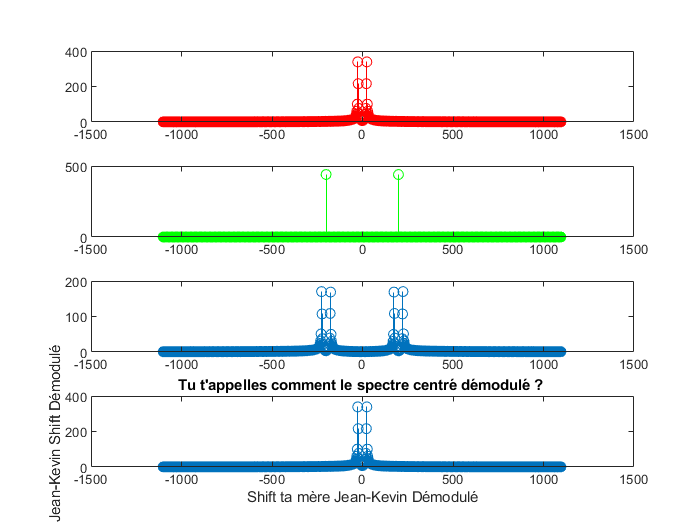

subplot(4,1,4)
stem(fs_N,Ds)
title("Tu t'appelles comment le spectre centré démodulé ? ")
xlabel("Shift ta mère Jean-Kevin Démodulé")
ylabel("Jean-Kevin Shift Démodulé ")

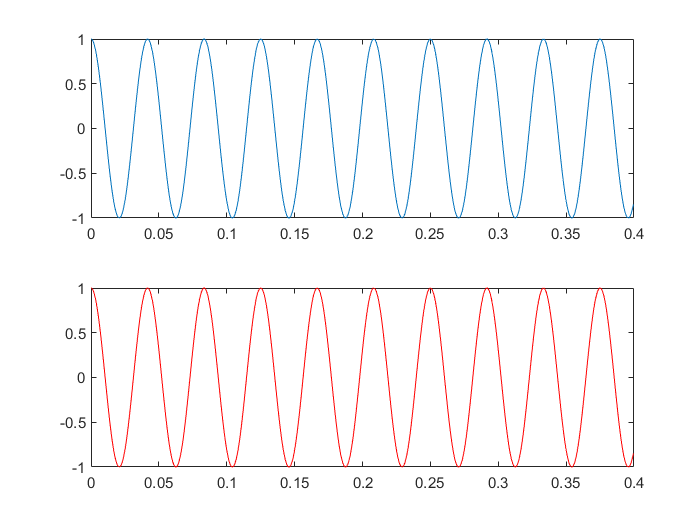


%question 15°) 
%On remarque les raies des signaux d(t) et x(t) sont identiques, on ne s'y
%attendait pas du touuuuuut. 

%Pour retrouver le signal x(t) à partir de z(t), il faut simplement retirer
%le signal y(t) de z(t) 

%question 16°) facultative 
%comparer d(t) et x(t) 
figure(5) 
subplot(2,1,1)
plot(t,d)
subplot(2,1,2)
plot(t,x,'r')